W_100_Heights = reshape(cell2mat(WHITE_100_Heights(:,3)),[],15)

W_100_Heights = 1.0e+04 *

    0.0387    0.5681    0.8882    0.9239    0.2047    0.3132    0.9148    0.0730    1.9224    0.0886    0.7625    0.9517    1.0027    1.5088    0.0160
    0.0618    0.8677    1.5588    1.4986    0.3644    0.4732    1.4856    0.1210    2.7085    0.1328    1.2585    1.5603    1.6240    2.4159    0.0160
    0.0970    1.2444    2.7490    2.4055    0.7130    0.6444    2.2820    0.2362    3.9003    0.1933    2.2033    2.7282    2.7303    3.9337    0.0160
    0.1529    1.5112    3.9588    3.3379    1.3282    0.8082    2.9771    0.5092    5.7540    0.2817    4.1369    4.7385    4.7388    6.5535    0.0160
    0.2374    2.1878    4.7280    4.2622    1.4679    1.2589    3.8869    0.5056    5.7540    0.4206    6.5535    6.5535    6.5535    6.5535    0.0160
    0.0073    0.0121    0.0854    0.0896    0.0510    0.0115    0.0357    0.0252    0.1398    0.0113    1.5761    1.9183    1.1462    3.1434    0.0160


W_100_H0_H6 = [WHITE{10,3}; W_100_Heights]

W_100_H0_H6 = 1.0e+04 *

    0.0460    0.6926    0.9669    0.9610    0.2018    0.3425    1.0931    0.0849    2.1738    0.1039    0.8571    0.9956    1.1296    1.6512    0.0160
    0.0387    0.5681    0.8882    0.9239    0.2047    0.3132    0.9148    0.0730    1.9224    0.0886    0.7625    0.9517    1.0027    1.5088    0.0160
    0.0618    0.8677    1.5588    1.4986    0.3644    0.4732    1.4856    0.1210    2.7085    0.1328    1.2585    1.5603    1.6240    2.4159    0.0160
    0.0970    1.2444    2.7490    2.4055    0.7130    0.6444    2.2820    0.2362    3.9003    0.1933    2.2033    2.7282    2.7303    3.9337    0.0160
    0.1529    1.5112    3.9588    3.3379    1.3282    0.8082    2.9771    0.5092    5.7540    0.2817    4.1369    4.7385    4.7388    6.5535    0.0160
    0.2374    2.1878    4.7280    4.2622    1.4679    1.2589    3.8869    0.5056    5.7540    0.4206    6.5535    6.5535    6.5535    6.5535    0.0160
    0.0073    0.0121    0.0854    0.0896    0.0510    0.0115    0.035

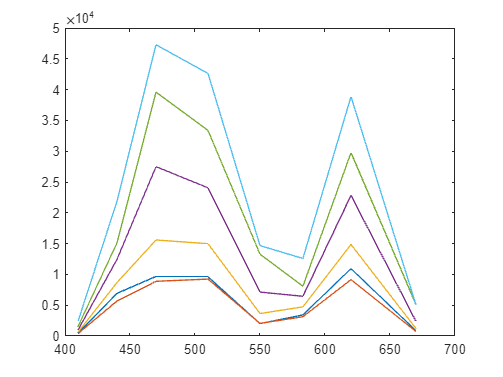

AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];

plot(AS_wavelengths,W_100_H0_H6(1,1:8))
hold on
for i = 2:6
    plot(AS_wavelengths,W_100_H0_H6(i,1:8))
end
hold off


distances = [0, 4, 7.8, 11.5, 14.5, 17.5, 20.5]

distances =          0    4.0000    7.8000   11.5000   14.5000   17.5000   20.5000


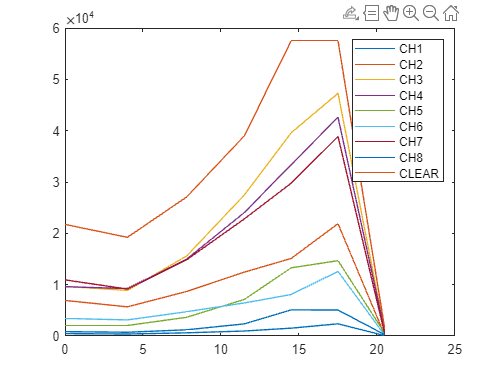


plot(distances,W_100_H0_H6(:,1))
hold on
for i = 2:9
    plot(distances,W_100_H0_H6(:,i))
end
legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR")
hold off

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(6,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end